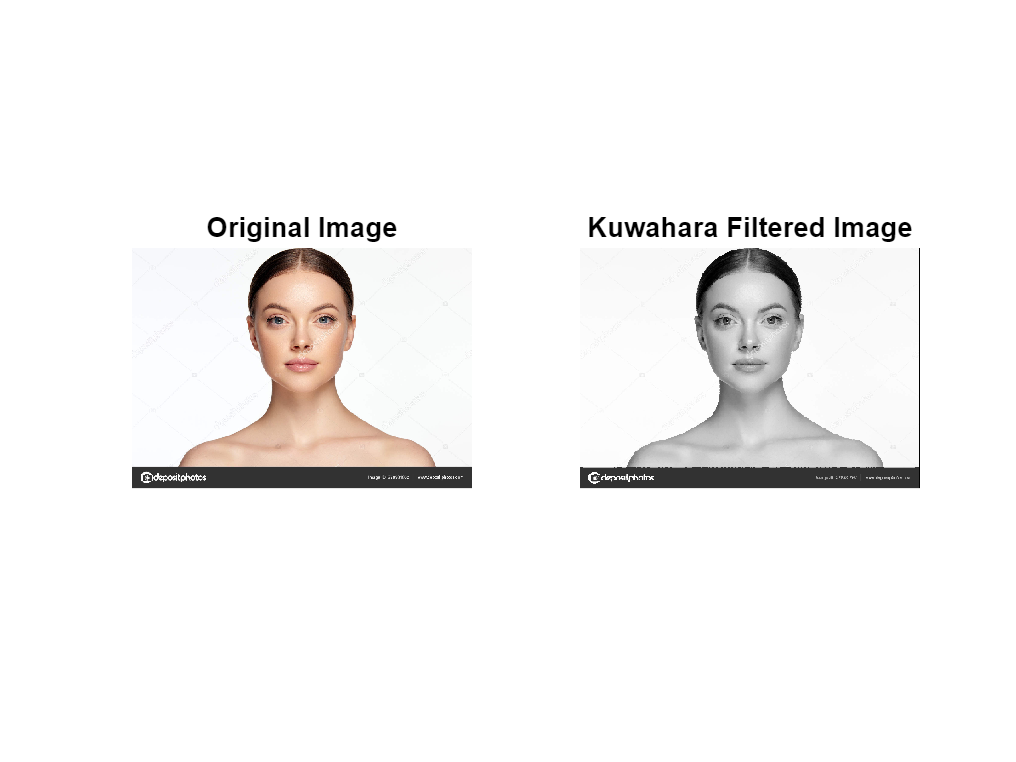

% Apply Kuwahara Filter
function filtered_image = kuwahara_filter(grayscale_image, window_size)
    % Get image dimensions
    [num_rows, num_cols] = size(grayscale_image); 
    filtered_image = zeros(num_rows, num_cols); % Initialize output image
    half_window = floor(window_size / 2);  % Half of the window size for neighborhood analysis

    % Convert the input grayscale image to double for accurate computations
    grayscale_image = double(grayscale_image);

    % Iterate through each pixel, excluding borders
    for row = 1 + half_window:num_rows - half_window
        for col = 1 + half_window:num_cols - half_window
            % Extract a local region around the current pixel
            local_region = grayscale_image(row-half_window:row+half_window, col-half_window:col+half_window);
            
            % Compute variances for the four quadrants of the local region
            quadrant_variances = zeros(1, 4);
            quadrant_variances(1) = var(var(local_region(1:half_window+1, 1:half_window+1)));         % Top-left quadrant
            quadrant_variances(2) = var(var(local_region(1:half_window+1, half_window+1:end)));      % Top-right quadrant
            quadrant_variances(3) = var(var(local_region(half_window+1:end, 1:half_window+1)));      % Bottom-left quadrant
            quadrant_variances(4) = var(var(local_region(half_window+1:end, half_window+1:end)));    % Bottom-right quadrant
            
            % Identify the quadrant with the lowest variance
            [~, min_variance_index] = min(quadrant_variances);
            
            % Select the corresponding quadrant based on the minimum variance
            switch min_variance_index
                case 1
                    selected_quadrant = local_region(1:half_window+1, 1:half_window+1);  % Top-left
                case 2
                    selected_quadrant = local_region(1:half_window+1, half_window+1:end); % Top-right
                case 3
                    selected_quadrant = local_region(half_window+1:end, 1:half_window+1); % Bottom-left
                case 4
                    selected_quadrant = local_region(half_window+1:end, half_window+1:end); % Bottom-right
            end
            
            % Compute the mean of the selected quadrant and assign it to the output pixel
            filtered_image(row, col) = mean(selected_quadrant(:));
        end
    end
    
    % Convert the filtered image back to uint8 for display
    filtered_image = uint8(filtered_image);
end

% Load and apply the Kuwahara filter to an image
original_image = imread('https://st4.depositphotos.com/6903990/27898/i/1600/depositphotos_278981062-stock-photo-beautiful-young-woman-clean-fresh.jpg');
grayscale_image = rgb2gray(original_image);  % Convert the image to grayscale
filtered_image = kuwahara_filter(grayscale_image, 5);  % Apply Kuwahara filter with a window size of 5

% Display the original and filtered images
figure;
subplot(1, 2, 1); imshow(original_image); title('Original Image');  % Show original image
subplot(1, 2, 2); imshow(filtered_image); title('Kuwahara Filtered Image');  % Show Kuwahara filtered image

The Kuwahara filter is a non-linear smoothing filter which retains an edge but diminishes the noise in an image. It works on dividing up a local neighborhood around each pixel into several subregions that overlap. The mean and variance are calculated in each subregion, and that region with the minimum variance is used to update the central pixel value. This method removes noise and increases the softness of areas with similar pixel values, but the edges and the details are preserved because regions which have less variance are selected, typically excluding edge regions.

The image processed by the Kuwahara filter was very smooth in skin areas by removing the fine textures and noise without removing the characteristic main facial features such as eyes, nose, and mouth. The result of the filter keeps the edges of those features sharp, but the vicinities, especially the skin, are very much softer and less resolved. That shows clearly how the filter noise reduction blurs selectively and does not let most of the edges blur at the same time, creating this kind of stylized look that just smoothes the homogeneous regions.